Q7

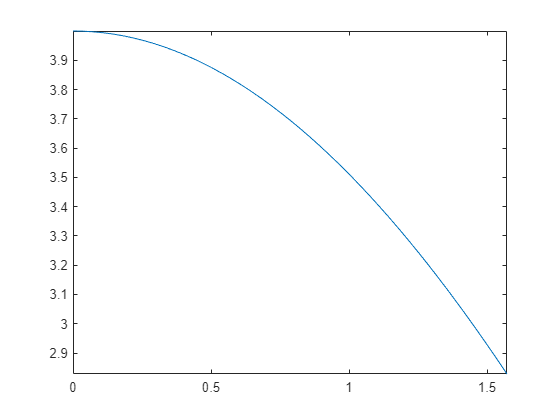

f = @(x) 4*cos(x./2);
a = 0;
b = pi/2;
fplot(f, [a b])

n = 2;
h = (b-a)/n;
I1 = (h/2)*(f(a)+f(a+h));

I1 = 3.0220

I2 = (h/2)*(f(a+h)+f(b));

I2 = 2.5619

I = I1+I2

I = 5.5840

Q8

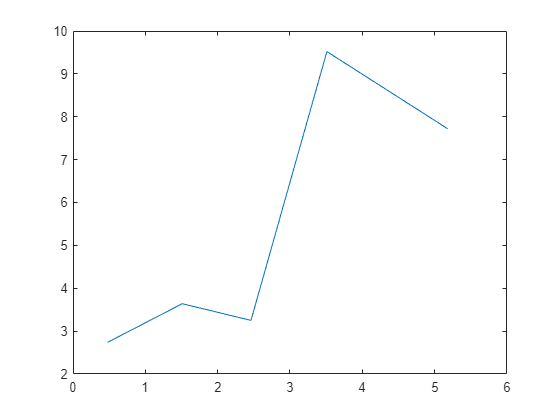

data = [0.48 1.51 2.46 3.51 5.18;
        2.74 3.64 3.25 9.52 7.72];
plot(data(1,:), data(2,:))

I = [];
for i = 1:(length(data(1,:))-1)
    I(i) = (data(1,i+1)-data(1,i))*((data(2,i)+data(2,i+1))/2);
end
sum(I)

ans = 27.6581

Q9

F = [7 1 9;
     1 8 9;
     2 7 3;
     5 5 5];
ax = 1;
bx = 8;
cy = 2;
dy = 6;
nx = 2;
ny = 3;
hx = (bx-ax)/nx;
hy = (dy-cy)/ny;

s38y1 = (3*hy)/8*(F(4,1) + 3*F(3,1) + 3*F(2,1) + F(1,1))

s38y1 = 10.5000

s38y2 = (3*hy)/8*(F(4,2) + 3*F(3,2) + 3*F(2,2) + F(1,2))

s38y2 = 25.5000

s38y3 = (3*hy)/8*(F(4,3) + 3*F(3,3) + 3*F(2,3) + F(1,3))

s38y3 = 25

s13x = hx/3*(s38y1 + 4*s38y2 + s38y3)

s13x = 160.4167

Q10

data = [1.50 2.50 3.50 4.50;
        1.53 6.08 2.23 0.87];
n = 3;
h = (data(1,end)-data(1,1))/n;
I = (3*h)/8*(data(2,1) + 3*data(2,2) + 3*data(2,3) + data(2,4))

I = 10.2488

Q11

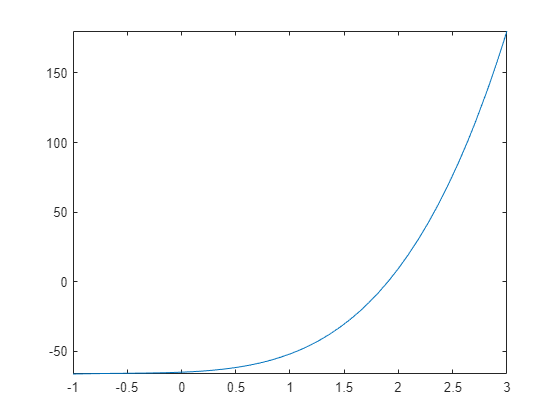

f = @(x) a4*x.^4 + a3*x.^3 + a2*x.^2 + a1*x + a0;
a = -1;
b = 3;
a4 = 1;
a3 = 4.1;
a2 = 4.9;
a1 = 3.1;
a0 = -65;
fplot(f, [a b])

c0 = 1;
c1 = 1;

x0 = -1/sqrt(3);
x1 = 1/sqrt(3);

alpha1 = (a+b)/2;
alpha2 = (b-a)/2;

g = @(xhat) f(alpha1 + alpha2*xhat)*alpha2;

I = c0*g(x0) + c1*g(x1)

I = -76.7556

integral(f,a,b)

ans = -71.0667

Q12

I11 = -.9215;
I12 = -.6798;
I13 = -.6348;
I21 = 4/3*I12 - 1/3*I11

I21 = -0.5992

I22 = 4/3*I13 - 1/3*I12

I22 = -0.6198

I31 = 16/15*I22 - 1/15*I21

I31 = -0.6212